## MathTools HW1

%% 2024-9-13
% Question 3

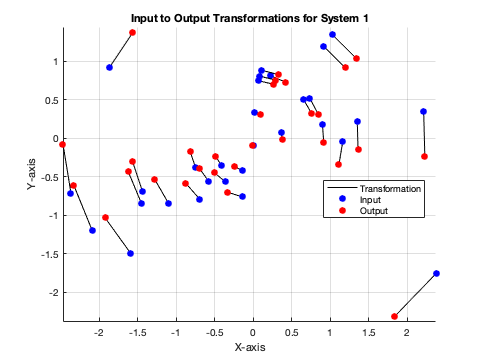

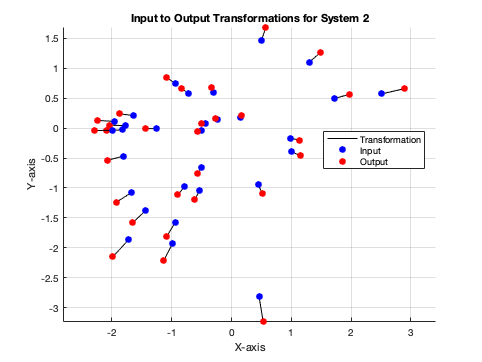

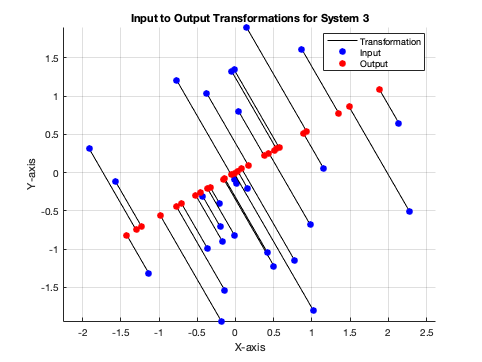

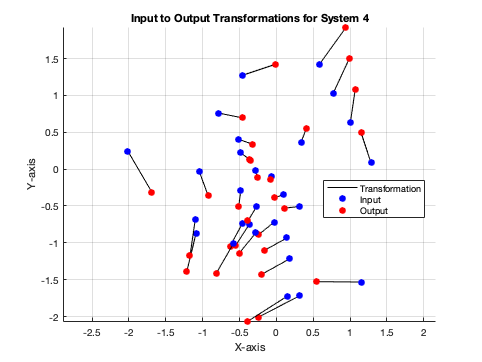

%a)

systems = {@sys1, @sys2, @sys3, @sys4}; 
sys_names = {'System 1', 'System 2', 'System 3', 'System 4'};

%Looping throught each system
for idx = 1:length(systems)
    system = systems{idx};
    system_name = sys_names{idx};

    %Generating 30 random 2D input vectors
    inputs = randn(30,2);

    %Empty holder for output
    outputs = zeros(30,2);

    % Compute outputs for each input
    for i = 1:30
        input_vector = inputs(i, :)';
        output_vector = system(input_vector);
        outputs(i, :) = output_vector';
    end

    figure; hold on;

    for i = 1:30
        input_point = inputs(i,:);
        output_point = outputs(i,:);

        plot([input_point(1), output_point(1)], [input_point(2), output_point(2)], 'k-', 'LineWidth', 0.5);
        plot(input_point(1), input_point(2), 'bo', 'MarkerFaceColor', 'b');
        plot(output_point(1), output_point(2), 'ro', 'MarkerFaceColor', 'r');
    end 

    %Labeling
    xlabel('X-axis');
    ylabel('Y-axis');
    title(['Input to Output Transformations for ', system_name]);
    legend('Transformation', 'Input', 'Output', 'Location', 'Best');

    grid on;
    axis equal;
    hold off;

end 

%b)
systems = {@sys1, @sys2, @sys3, @sys4}; 
sys_names = {'System 1', 'System 2', 'System 3', 'System 4'};
Ms = {}; 

% Loop over each system
for idc = 1:length(systems)
    system = systems{idc};
    system_name = sys_names{idc};
    
    fprintf('Analyzing %s\n', system_name);
    
    %Set some random simple impulses
    e1 = [1; 0];
    e2 = [0; 1];
    
    % Obatin each system's response to impulses
    m1 = system(e1);  
    m2 = system(e2);  
    
    % Construct M
    M = [m1, m2];
    Ms{idc} = M; 
    fprintf('Matrix M for %s:\n', system_name);
    disp(M);
    
    %SVD of M
    [U, S, V] = svd(M);
    
    fprintf('Singular Values for %s:\n', system_name);
    disp(diag(S));
    
    fprintf('Matrix U for %s:\n', system_name);
    disp(U);
    fprintf('Matrix Vt for %s:\n', system_name);
    disp(V');
    
%     fprintf('Explanation for %s:\n', system_name);
%     if strcmp(system_name, 'System 1')
%         fprintf(['According to the SVD, the system (system 1) is first rotating input vectors by 90-degrees counterclockwise,' ...
%             'but perserving its magnitude, and then rotated an additional 75-degrees counterclockwise (after no scaling).']);
%     elseif strcmp(system_name, 'System 2')
%         fprintf(['For this system (system 2), there is no rotation or reflection, but the input vector has been' ...
%             'equally scaled along both axes by 1.15. And there is no rotation or reflection after scaling,' ...
%             'it remains in the same orientation.']);
%     elseif strcmp(system_name, 'System 3')
%         fprintf(['Firstly, the system 3 rotates input vectors by 150-degrees counterclockwise, then it projects the rotated vector x onto the first axis.' ...
%             'Finally, it rotates the vector by another 150-degree counterclockwise and the reflected.']);
%     elseif strcmp(system_name, 'System 4')
%         fprintf(['The system 4 firstly rotated the vector by 60-degree and refelcts it across a line. Then, it stretched the vector along one axis and ' ...
%             'compresses it along another axis. Finally, it rotated results from s by another 60-degree and reflected it again.']);
%     end %if
    
    fprintf('---\n\n');
end

Analyzing System 1


Matrix M for System 1:


    0.9659    0.2588
   -0.2588    0.9659



Singular Values for System 1:


    1.0000
    1.0000



Matrix U for System 1:


    0.2588   -0.9659
    0.9659    0.2588



Matrix Vt for System 1:


     0     1
    -1     0



---



Analyzing System 2


Matrix M for System 2:


    1.1500         0
         0    1.1500



Singular Values for System 2:


    1.1500
    1.1500



Matrix U for System 2:


     1     0
     0     1



Matrix Vt for System 2:


     1     0
     0     1



---



Analyzing System 3


Matrix M for System 3:


    0.7500    0.4330
    0.4330    0.2500



Singular Values for System 3:


    1.0000
    0.0000



Matrix U for System 3:


   -0.8660   -0.5000
   -0.5000    0.8660



Matrix Vt for System 3:


   -0.8660   -0.5000
    0.5000   -0.8660



---



Analyzing System 4


Matrix M for System 4:


    0.8750    0.3031
    0.3031    1.2250



Singular Values for System 4:


    1.4000
    0.7000



Matrix U for System 4:


    0.5000    0.8660
    0.8660   -0.5000



Matrix Vt for System 4:


    0.5000    0.8660
    0.8660   -0.5000



---



Part B Explanations:

**System 1:** According to the SVD, the system (system 1) is first rotating input vectors by 90-degrees counterclockwise, but perserving its magnitude, and then rotated an additional 75-degrees counterclockwise (after no scaling).

**System2: **For this system (system 2), there is no rotation or reflection, but the input vector has been equally scaled along both axes by 1.15. And there is no rotation or reflection after scaling, it remains in the same orientation.

**System3: **Firstly, the system 3 rotates input vectors by 150-degrees counterclockwise, then it projects the rotated vector x onto the first axis. Finally, it rotates the vector by another 150-degree counterclockwise and the reflected.

**System4: **The system 4 firstly rotated the vector by 60-degree and refelcts it across a line. Then, it stretched the vector along one axis and compresses it along another axis. Finally, it rotated results from s by another 60-degree and reflected it again.

Plotting square passing through System 1


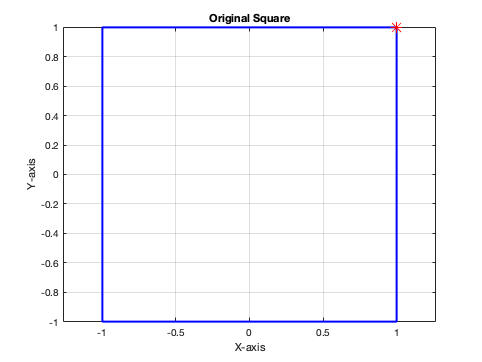

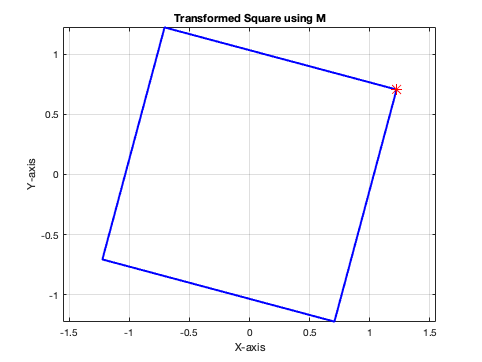

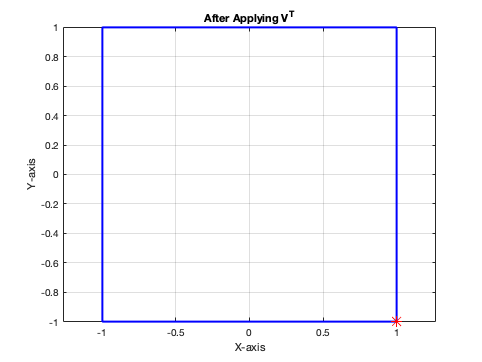

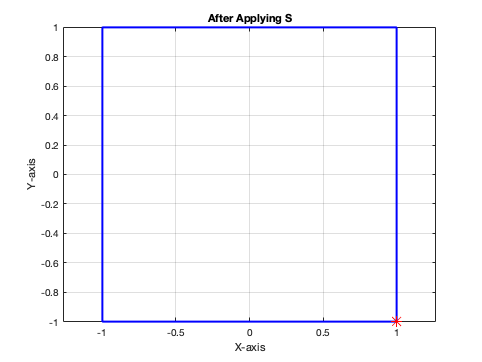

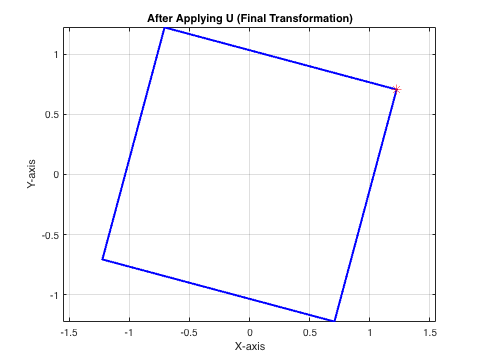

Plotting square passing through System 2


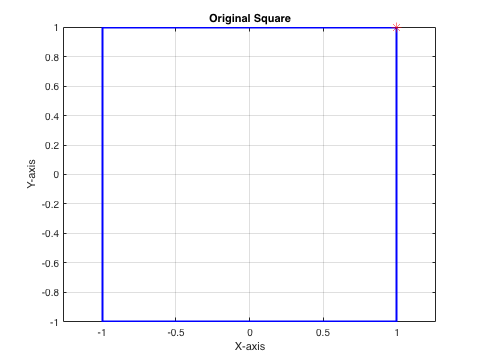

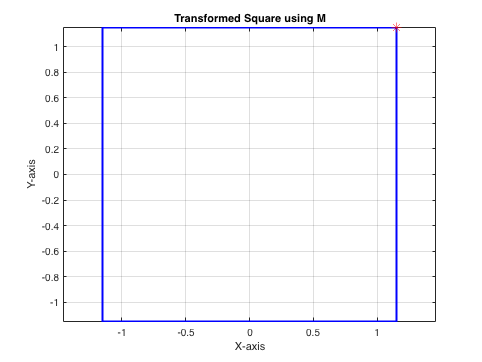

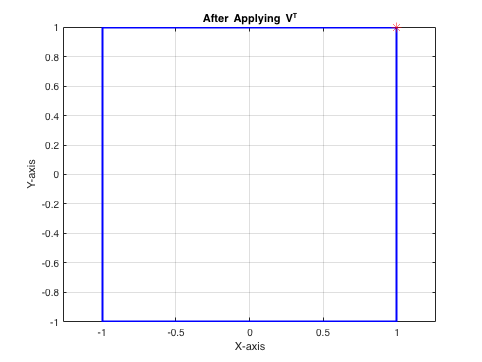

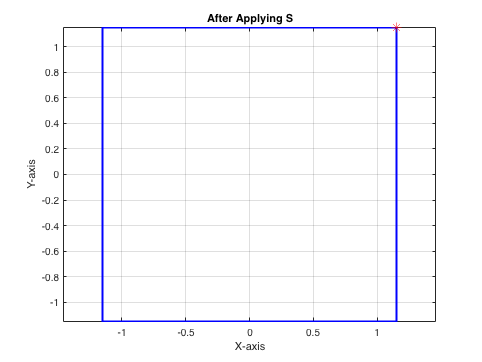

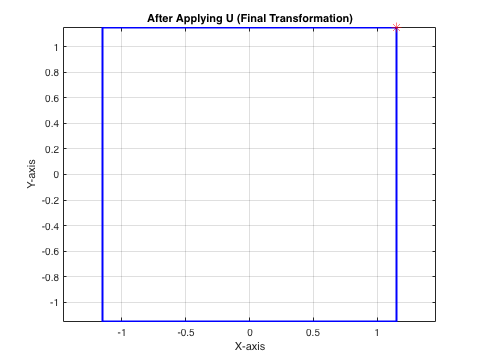

Plotting square passing through System 3


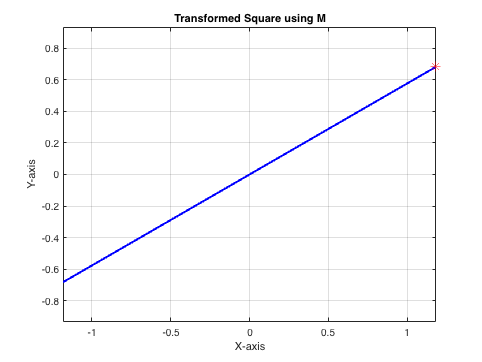

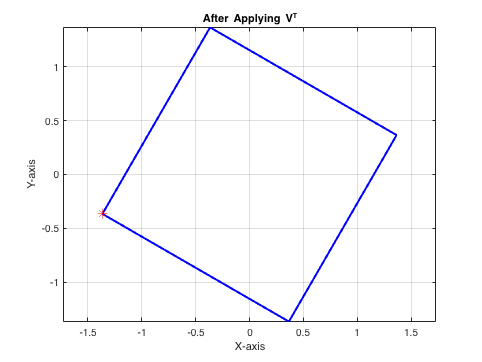

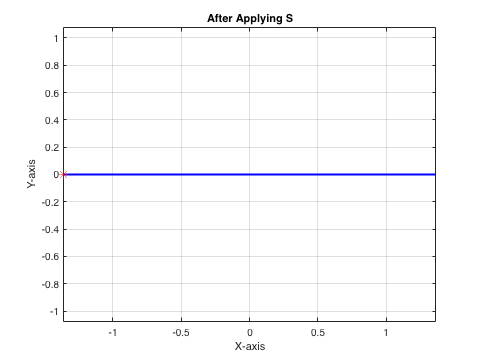

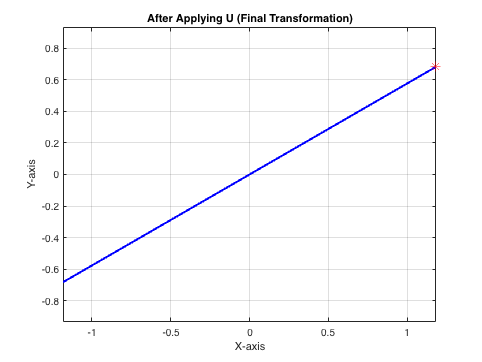

Plotting square passing through System 4


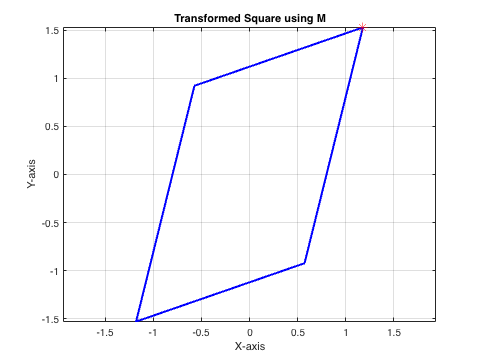

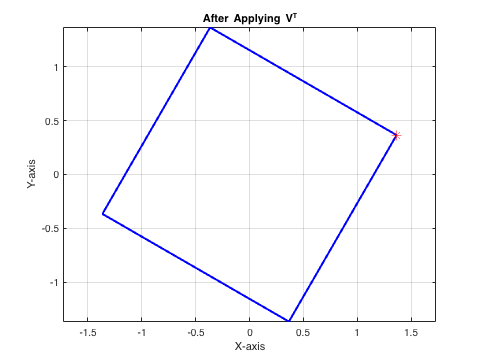

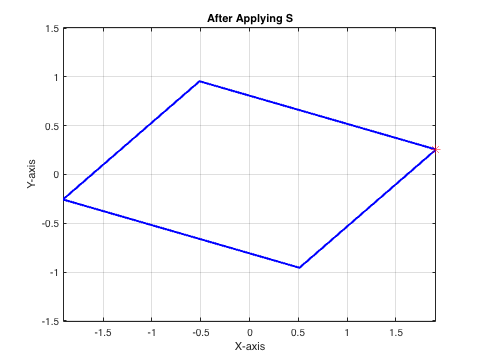

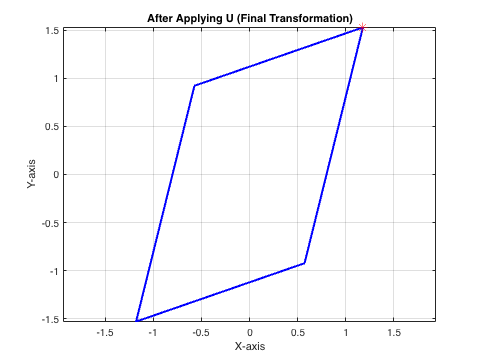

%c)

for idz = 1:length(systems)
    system = systems{idz};
    system_name = sys_names{idz};
    
    fprintf('Plotting square passing through %s\n', system_name);

% Generate the data matrix P
P = [  0,  1,  1,  1,  0, -1, -1, -1;
       1,  1,  0, -1, -1, -1,  0,  1 ];

P_closed = [P, P(:,1)];

% Plot the original square
figure;
plot(P_closed(1, :), P_closed(2, :), 'b-', 'LineWidth', 2);
hold on;
plot(P(1, 2), P(2, 2), 'r*', 'MarkerSize', 10);
xlabel('X-axis');
ylabel('Y-axis');
title('Original Square');
axis equal;
grid on;
hold off;

M = Ms{idz}; 

% Apply M to P
P_transformed = M * P;

% Plot the transformed square
P_transformed_closed = [P_transformed, P_transformed(:,1)];
figure;
plot(P_transformed_closed(1, :), P_transformed_closed(2, :), 'b-', 'LineWidth', 2);
hold on;
plot(P_transformed(1, 2), P_transformed(2, 2), 'r*', 'MarkerSize', 10);
xlabel('X-axis');
ylabel('Y-axis');
title('Transformed Square using M');
axis equal;
grid on;
hold off;

% Compute the SVD of M
[U, S, V] = svd(M);

% Apply the transformations step by step
P_step1 = V' * P;         
P_step2 = S * P_step1;    
P_step3 = U * P_step2;    

% Verify that P_step3 equals P_transformed
assert(norm(P_step3 - P_transformed, 'fro') < 1e-10, 'Mismatch in transformations');

% Plot after applying V^T
P_step1_closed = [P_step1, P_step1(:,1)];
figure;
plot(P_step1_closed(1, :), P_step1_closed(2, :), 'b-', 'LineWidth', 2);
hold on;
plot(P_step1(1, 2), P_step1(2, 2), 'r*', 'MarkerSize', 10);
xlabel('X-axis');
ylabel('Y-axis');
title('After Applying V^T');
axis equal;
grid on;
hold off;

% Plot after applying S
P_step2_closed = [P_step2, P_step2(:,1)];
figure;
plot(P_step2_closed(1, :), P_step2_closed(2, :), 'b-', 'LineWidth', 2);
hold on;
plot(P_step2(1, 2), P_step2(2, 2), 'r*', 'MarkerSize', 10);
xlabel('X-axis');
ylabel('Y-axis');
title('After Applying S');
axis equal;
grid on;
hold off;

% Plot after applying U
P_step3_closed = [P_step3, P_step3(:,1)];
figure;
plot(P_step3_closed(1, :), P_step3_closed(2, :), 'b-', 'LineWidth', 2);
hold on;
plot(P_step3(1, 2), P_step3(2, 2), 'r*', 'MarkerSize', 10);
xlabel('X-axis');
ylabel('Y-axis');
title('After Applying U (Final Transformation)');
axis equal;
grid on;
hold off;
end 


disp('Overall, having the square as a visualization helped better understanding how those systems are changing the inputs.')

Overall, having the square as a visualization helped better understanding how those systems are changing the inputs.
